clc
%clear all
format short
alphastall=deg2rad(13); %LIEBECK LPT 110A
Cmac=0.025; %airfoil property
aspectratio=7.79;
alpha_o=deg2rad(0.5); %airfoil property
eta=0.98; % leading edge suction efficiency
rho= 1.1033; % density of air(kg/m3) at 500m
%f=9.27; % flapping frequency (Hz) %FIXING FOR NOW
U=10; % forward velocity (m/s)
mew=1.8458*10^-5; % (coefficient of viscocity(Ns/m2) or in (kg/ms)) at 500m
%dt=1/(20*f); %time interval
dy=0.04616/2;%section width (for each of 10 sections)
ddy=dy*10; %half span in m
%%%%%%%%%%%%%%%%%%%%%%%%%% PARAMETERS THAT CAN BE CHANGED %%%%%%%%%%%%%%%%%%%%
theta_a=deg2rad(6); % pitching angle of flapping angle with respect to U(rad)
gamma=deg2rad(120/2); % maximum flapping
%%%%%%%%%%%%%%%%%%%%%%%%%%
f_u = 7.93; % in Hz
f_l = 7.01; %in Hz
gamma_u = rad2deg(2*asin((0.3*U)/(f_l*ddy*2))) %upper limit for max flapping angle - 135.9814 deg

gamma_u = 135.9814

gamma_l = rad2deg(2*asin((0.3*U)/(f_u*ddy*2))) %lower limit for mx flapping angle - 110.0821 deg

gamma_l = 110.0821

%%%%%%%%%%%%%%%%%%%%%%%%%%
span = [0 0.0186915 0.0381958 0.0577 0.0772042 0.0967085 0.1154 0.134904 0.153596 0.1731 0.192604 0.212108 0.2308]

span =          0    0.0187    0.0382    0.0577    0.0772    0.0967    0.1154    0.1349    0.1536    0.1731    0.1926    0.2121    0.2308


c = [0.0740984 0.0681967 0.0636066 0.0616393 0.0609836 0.0596721 0.0557377 0.052459 0.0498361 0.0478689 0.02950815 0.01508195 0]

c =     0.0741    0.0682    0.0636    0.0616    0.0610    0.0597    0.0557    0.0525    0.0498    0.0479    0.0295    0.0151         0


beta= -20:0.82021:20; % deg/meter (1 to 6.096 in intervals of 0.25) deg per feet
a = 5:0.5:10

a =     5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


p = 5

theta_a = 0.0873

f = 7.5046

p = 5.5000

theta_a = 0.0960

f = 7.5046

p = 6

theta_a = 0.1047

f = 7.5046

p = 6.5000

theta_a = 0.1134

f = 7.5046

p = 7

theta_a = 0.1222

f = 7.5046

p = 7.5000

theta_a = 0.1309

f = 7.5046

p = 8

theta_a = 0.1396

f = 7.5046

p = 8.5000

theta_a = 0.1484

f = 7.5046

p = 9

theta_a = 0.1571

f = 7.5046

p = 9.5000

theta_a = 0.1658

f = 7.5046

p = 10

theta_a = 0.1745

f = 7.5046

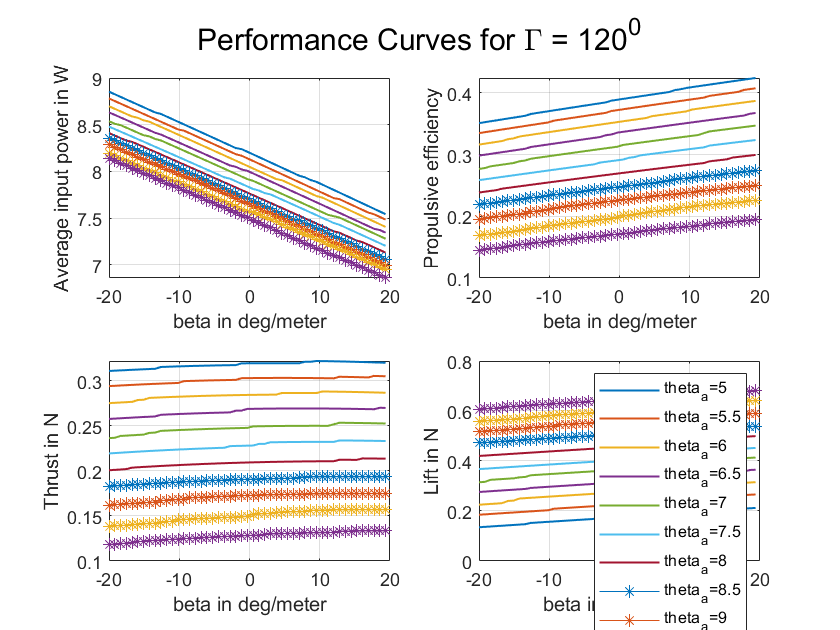

for p=a
    p
    theta_a = deg2rad(p)
    f = (0.3*U)/(ddy*2*sin(gamma))
    dt=1/(20*f); %time interval %THIS ALSO CHANGES WITH GAMMA
for z=1:length(beta)
    theta_o=deg2rad(beta(z)); % pitching motion amplitude(rad/feet)
    for x = 1:1:12
        o=((pi*f*c(x))/U); % reduced frequency
        count=1;
        for t = 0:dt:1/f
            dihedral=gamma*cos(2*pi*f*t);
            theta=-(theta_o*span(x)*sin(2*pi*f*t))+theta_a;
            h=-gamma*span(x)*cos(2*pi*f*t);
            hdot=gamma*span(x)*sin(2*pi*f*t)*2*pi*f;
            hdoubledot=-((2*pi*f)^2)*h;
            thetadot=-theta_o*span(x)*cos(2*pi*f*t)*2*pi*f;
            thetadoubledot=theta_o*span(x)*sin(2*pi*f*t)*2*pi*f*2*pi*f;
            Vpitch=0.75*c(x)*thetadot;
            Vplunge=hdot*cos(theta-theta_a);
            Downwardvelocity=U*(theta-theta_a);
            Vpitchdot=0.75*c(x)*thetadoubledot;
            Vplungedot=-hdot*sin(theta-theta_a)*thetadot+hdoubledot*cos(theta-theta_a);
            Downwardvelocitydot=U*thetadot;
            temp(x,count)=(Vpitch+Vplunge+Downwardvelocity)/U;
            alpha=(temp(x,count));
            angle(x,count)= (((Vpitchdot+Vplungedot+Downwardvelocitydot)/U))*180/pi;
            alphadot=(Vpitchdot+Vplungedot+Downwardvelocitydot)/U;
            AR=aspectratio;
            C1=(0.5*AR)/(2.32+AR);
            C2=(0.181)+(0.772/AR);
            F=1-((C1*o^2)/(o^2+C2^2));
            G=-((C1*C2*o)/(o^2+C2^2));
            C=(F^2+G^2)^0.5;
            w=(U*2*(alpha_o+theta_a))/(2+AR);
            alphap=((AR/(2+AR))*(F*alpha+(c(x)/(2*U))*(G/o)*alphadot))-w/U;
            b=(U*alphadot)-(0.25*c(x)*thetadoubledot);
            Vx=(U*cos(theta))-(hdot*sin(theta-theta_a));
            % velocityx(x,count)=U*cos(theta)-hdot*sin(theta-theta_a);
            tempp(x,count)=(((alphap+theta_a-(0.75*c(x)*thetadot/U))))*180/pi;
            if (alphap+theta_a-((0.75*c(x)*thetadot)/U)) >= alphastall
                Vn=hdot*cos(theta-theta_a)+0.5*c(x)*thetadot+U*sin(theta);
                Vs=sqrt((Vx^2+Vn^2));
                dNc(x,count)=(1.98*Vs*Vn*c(x)*rho*dy)/2;
                dNa(x,count)=(rho*pi*c(x)^2*dy*b)/8;
                dDf(x,count)=0;
                dTs(x,count)=0;
                dDcamb(x,count)=0;
                dPin(x,count)=(dNc(x,count)+dNa(x,count))*(hdot*cos(theta-theta_a)+0.5*c(x)*thetadot);
                dL(x,count)=((dNa(x,count)+dNc(x,count))*cos(theta))+((dTs(x,count)-dDf(x,count)-dDcamb(x,count))*sin(theta))*cos(dihedral);
                dT(x,count)= ((dTs(x,count)-dDf(x,count)-dDcamb(x,count))*cos(theta))-((dNa(x,count)+dNc(x,count))*sin(theta));
            else
                Vy=(U*(alphap+theta_a))-(0.5*c(x)*thetadot);
                % velocityy(x,count)=U*(alphap+theta_a)-0.5*c(x)*thetadot;
                V=sqrt((Vx)^2+(Vy)^2);
                dDcamb(x,count)=-2*pi*alpha_o*(alphap+theta_a)*rho*U*V*c(x)*dy*0.5;
                dNc(x,count)=rho*U*V*pi*(alphap+theta_a+alpha_o)*dy*c(x);
                %circulatory normal force
                dNa(x,count)=(rho*pi*(c(x)^2)*b*dy)/4; %normal force due to apparent mass effect
                dTs(x,count)=eta*2*pi*((alphap+theta_a-((0.25*c(x)*thetadot)/U))^2)*rho*U*(V/2).*dy*c(x); %leading edge suction force
                re=(rho*U*c(x))/(mew);
                Cdf(x,count)=0.89/((log10(re))^2.58);
                dDf(x,count)=Cdf(x,count)*rho*((Vx)^2)*c(x)*dy*0.5; %friction drag
                dFx=(dTs(x,count)-dDcamb(x,count)-dDf(x,count));
                dN=((dNa(x,count)+dNc(x,count)));
                dL(x,count)=(dN*cos(theta)+dFx*sin(theta))*cos(dihedral);
                dT(x,count)= (dFx*cos(theta))-(dN*sin(theta));
                dM=-(((rho*pi*(c(x)^3)*thetadot*U)/16)+(rho*pi*(c(x)^4)*thetadoubledot)/128)*dy;
                dmac=Cmac*rho*dy*(c(x).^2)*U*V*0.5;
                dPin(x,count)=((dFx)*hdot*sin(theta-theta_a))+((dN)*(hdot*cos(theta-theta_a)+(0.25*c(x)*thetadot)))+(0.25*c(x)*thetadot*dNa(x,count))-((dM+dmac)*thetadot);
            end
            time(count)=t;
            count=count+1;
        end
    end
    avglift=0;
    avgthrust=0;
    avgpower=0;
    for i=1:count-1
        lift(i)=0;
        thrust(i)=0;
        power(i)=0;
    end
    for i=1:count-1
        for k=1:x
            lift(i)=lift(i)+dL(k,i);
            thrust(i)=thrust(i)+dT(k,i);
            power(i)=power(i)+dPin(k,i);
        end
        avglift=avglift+lift(i)*dt;
        avgthrust=avgthrust+thrust(i)*dt;
        avgpower=avgpower+power(i)*dt;
    end
    avgliftt(z)=avglift*f;
    avgthrustt(z)=avgthrust*f;
    averagepowerinput(z)=avgpower*f;
    efficiency(z)=(avgthrustt(z)*U)/averagepowerinput(z);
end

%figure(1)
subplot(2,2,1)
grid on
if rad2deg(theta_a)<=8
    plot(beta,2*averagepowerinput, 'linewidth',1)
    hold on
else
    plot(beta,2*averagepowerinput,'-*')
    hold on
end
xlabel('beta in deg/meter')
ylabel('Average input power in W')

subplot(2,2,2)
grid on
if rad2deg(theta_a)<=8
    plot(beta,efficiency, 'linewidth',1)
    hold on
else
    plot(beta,efficiency,'-*')
    hold on
end
ylabel('Propulsive efficiency')
xlabel('beta in deg/meter')

subplot(2,2,3)
grid on
if rad2deg(theta_a)<=8
    plot(beta,2*avgthrustt, 'linewidth',1)
    hold on
else
    plot(beta,2*avgthrustt,'-*')
    hold on
end
% plot(beta,2*avgthrustt)
xlabel('beta in deg/meter')
ylabel('Thrust in N')

subplot(2,2,4)
grid on
if rad2deg(theta_a)<=8
    plot(beta,2*avgliftt, 'linewidth',1)
    hold on
else
    plot(beta,2*avgliftt,'-*')
    hold on
end
% plot(beta,2*avgliftt)
ylabel('Lift in N')
xlabel('beta in deg/meter')
sgtitle('Performance Curves for \Gamma = 120^0')
legend('theta_a=5','theta_a=5.5','theta_a=6','theta_a=6.5','theta_a=7','theta_a=7.5','theta_a=8','theta_a=8.5','theta_a=9','theta_a=9.5','theta_a=10')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end

% [AX,H1,H2] = plotyy(beta,2*ll,beta,2*tt,'plot')

% set(get(AX(1),'Ylabel'),'String','Avg Lift(lbf)')
% set(get(AX(2),'Ylabel'),'String','Avg Thrust(lbf)')
% yyaxis left
% plot(beta,2*avgliftt)
% yyaxis right
% plot(beta,2*avgthrustt)